# 3.15

Consider a LTI described by the following input-output relation:

y[n] = 3/4 y[n − 1] − 1/8 y[n − 2] + x[n].

(a) Find the system function H(z) and check whether the system is stable.

(b) Determine the impulse response h[n] of the system.

(c) Determine the step response s[n] of the system.

(d) Compute h[n] and s[n] for 0 ≤ n ≤ 10 using the formulas in (b) and (c) and

compare with the values obtained using the function filter.

b = [1]; a = [1,-0.75,0.125]; [R,p,C] = residuez(b,a)

R =      2
    -1


p =     0.5000
    0.2500



C =

     []



[b,a] = residuez(R,p,C)

b =      1     0


a =     1.0000   -0.7500    0.1250


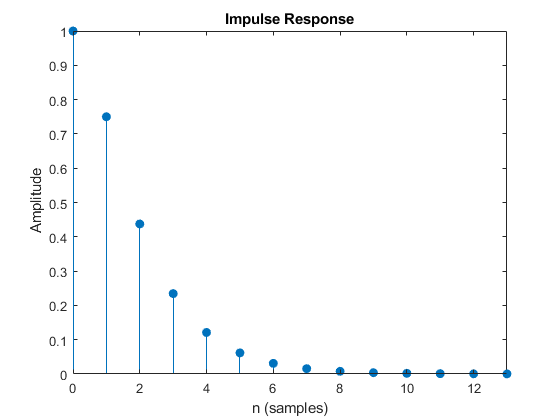

impz(b,a)

h = filter(b,a,[1 0 0 0 0 0 0 0 0 0])

h =     1.0000    0.7500    0.4375    0.2344    0.1211    0.0615    0.0310    0.0156    0.0078    0.0039


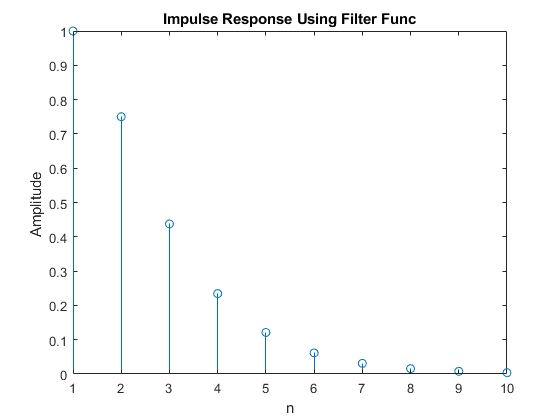

stem(h)
title('Impulse Response Using Filter Func') ; xlabel('n') ; ylabel('Amplitude ')

s = filter(b,a,ones(1,10))

s =     1.0000    1.7500    2.1875    2.4219    2.5430    2.6045    2.6355    2.6511    2.6589    2.6628


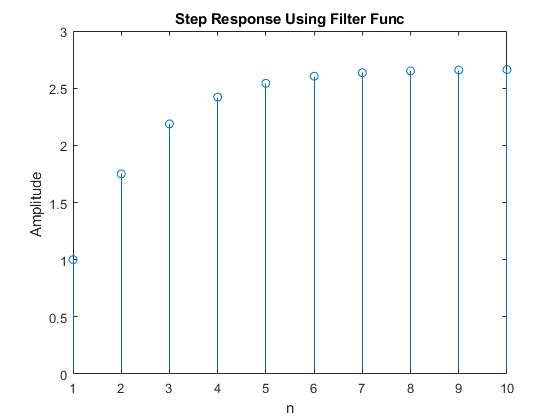

stem(s)
title('Step Response Using Filter Func') ; xlabel('n') ; ylabel('Amplitude ')

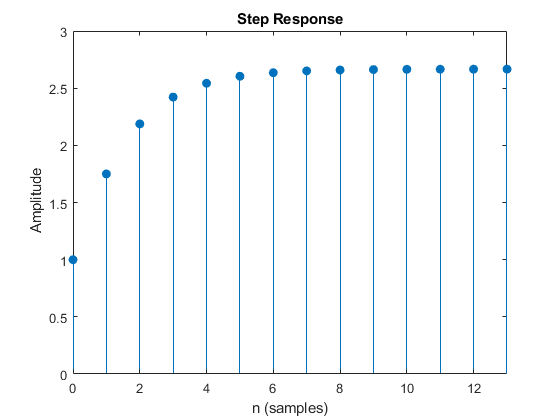

stepz(b,a)